# Record.writesmr demo

The `writesmr` method of `Record` class allows you to save the content of a `Record `object into a 32 bit Spike2 `.smr` file.

**See also**

`Record.writesmr`

`EventChan_test`

`WaveformChan_test`

`MarkerChan_test`

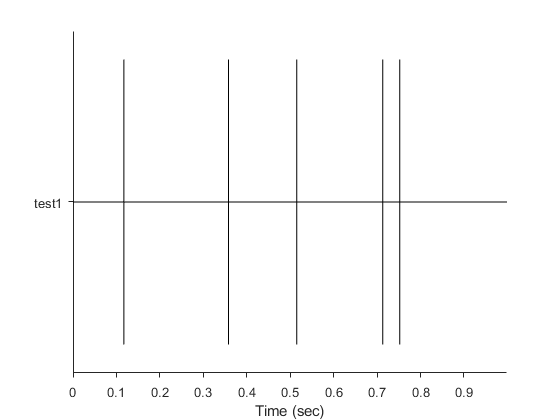

close all;clear; clc;

Fs = 1000;
rng('default') % To get reproducible results
e = double(logical(poissrnd(10/Fs, 1000, 1)));

E = EventChan(e, 0, Fs, 'test1'); % 370 byte
E.plot;


rec = Record({E},'Name','foo0');

rec.writesmr('foo0.smr')

ans = 0

foo0.smr


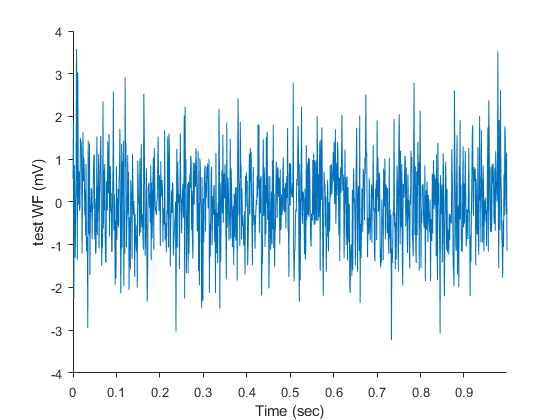

Fs = 1000;
rng('default') % To get reproducible results
a = randn(1000, 1);
W = WaveformChan(a, 0, Fs, 'test WF');
W.plot;


rec = Record({W},'Name','hoge');

rec.writesmr('foo1.smr')

ans = 0

foo1.smr


Fs = 1000;
rng('default');
events = double(logical(poissrnd(30/Fs, 1000, 1)));

ind1 = find(events);
codes  = logical(poissrnd(3/10, length(ind1), 1)) ...
    + logical(poissrnd(2/10, length(ind1), 1)) .*2 ...
    + logical(poissrnd(1/10, length(ind1), 1)) .*3 

codes =      2
     2
     3
     0
     3
     0
     0
     1
     1
     3


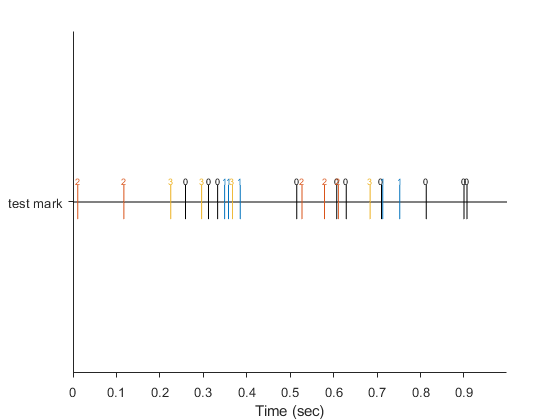


M = MarkerChan(events, 0, Fs, codes, 'test mark'); % 370 byte
h = M.plot;


rec = Record({M},'Name','hoge');

rec.writesmr('foo2.smr')

ans = 0

Elapsed time is 0.297751 seconds.
foo2.smr


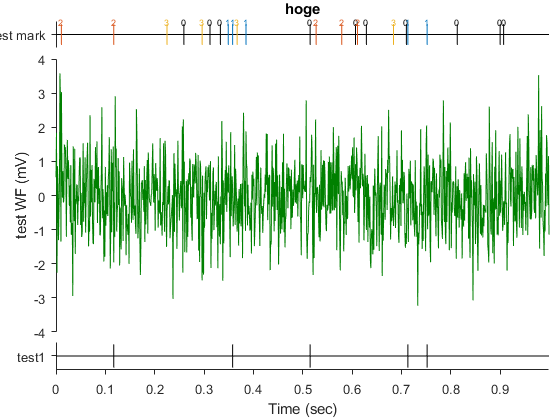

rec = Record({E,W,M},'Name','hoge');
rec.plot;


rec.writesmr('foo3.smr')

ans = 0

Elapsed time is 0.256152 seconds.
foo3.smr
